# Lab 2: Convolution with MATLAB

## Section 1: What is convolution?

Just like addition and multiplication, convolution is a linear operator that acts on scalars, vectors, or infinite dimensional vectors called functions. In fact it inherits its linearity from the integral it is defined by, namely:


$$\[
(x * h)(t)
:= \int_{-\infty}^{\infty} x(\tau)\, h(t - \tau)\, d\tau
\]
$$


The problem with the above definition is that it is hard to visualize what exactly is happening to the sets x and h when under the convolution operation. The integral is being evaluated with respect to the dummy variable $$\tau$$ and hence the output is a function of only t. 

In class, convolution is described only in terms of convolving two functions, but as mentioned before it is a linear operator that may act on vectors and scalars - otherwise it would be very hard to implement in MATLAB. When convolution acts on two scalars, in other words single element vectors, it behaves the same as mutliplication. This can be derived from the integral expression above, along with a trick. Since scalars are not time dependent, one can construct a signal equivalent of a scalar by letting its area equal that scalar, in other words $x(t) = x\delta(t)
$. Plugging the same in for h(t) into the integral yields:


$$\[
(x * h)(t)
:= \int_{-\infty}^{\infty} x(\tau)\, h(t - \tau)\, d\tau = xh\int_{-\infty}^{\infty} \delta(\tau)\delta(t-\tau) d\tau = xh
\]$$


For the application of convolution to vectors, you can think of it very similarly to how it is discussed in class, by flipping one of the vectors by 180 degrees, and then sliding it over the elements of the second vector and element wise multiplying the directly overlaying values and taking their sum. Say the first vector is A = [1, 2, 3] and the second vector is B = [4, 5]. To convolve A and B, namely to evalutate A*B, the following process is undertaken:

Step 1: Flip B by 180 degrees

This results in B' = [4, 5].

Step 2: Iteratively slide B' over the elements of A, and with each step compute the element wise product and take the sum:

Yielding the first product sum = 1*5, hence A*B = [5]

1*4 + 2*5 = 14, hence A*B is updated to = [5, 14]

2*4 + 3*5 = 23, hence A*B is updated to = [5, 14, 23]

3*4 = 12, yeilding a final result of A*B = [5, 14, 23, 12]. Notice how the first vector A had size = 3, and the second had size = 2, while the result of the convolution is neither. In fact if the first vector has size 'n' and the second has size 'm', the A*B has size **n+m-1**.

Notice how the process above is precisely what you have been doing with functions! A 'summed product' for continuous functions is precisely what integration is, and the $(t-\tau)
$ term is the 180 degree rotation. It still evalutes point wise, but due to the density of the elements of each function the summed product approaches the integral in the limit. In this lab, we will be dealing with discrete vectors as shown above, not functions, but the process of evaluting the convolution is 1:1. Moreover, by increasing the density of the domain of each vector (namely by reducing $\Delta t
$), the plotted output will be indiscernable from the continuous case. 

## Section 2: Why do we care about convolution?

When dealing with linear systems such as RLC circuits or spring-mass-dampers, we want to know how be able to predict how the output of the system changes with respect to the input. Say we are using a spring-mass-damper system to model a helicopter and we want it to hover at a particular altitude. The thrust supplied by the helicopter can be considered the input to the system, and the respective altitude is the output. Depending on the way the thrust is applied determines how we reach that target altitude - does the system overshoot the target and start to oscillate about it, or does the helicopter slowly approach the setpoint slowing down gradually as it approaches it eventually coming to a standstill? These outputs can be designed for by knowing how the helicopter will react given particular thrust (input) functions. 

The impulse response of a linear time invariant (LTI) system is this function that we need to fully characterize the system. The input x(t) and output y(t) of an LTI is related via the following equation:


$$y(t) = h(t)*x(t)
$$


Where (*) denotes convolution. Thus, if we know h(t) then regardless of the input x(t) we will know how the system responds. That is of course if we know how to convolve functions/vectors!

Another example of the use of convolution lies is statistics (which you will go into more depth in signals 2). Given two random variables X and Y related by another random variable Z = X + Y and each with probability distributions $f_X (x)$ and $f_Y(y)$ then the distribution of Z is:


$$\[
f_{Z}(z) = \int_{-\infty}^{\infty} f_{XY}(x,\, z - x)\, dx
\]
$$


And if X and Y are independent random variables then $f_{XY}(x,\, z - x) = f_X(x)f_Y(z-x)$ thus:


$$\[
f_{Z}(z) = \int_{-\infty}^{\infty} f_{XY}(x,\, z - x)\, dx = \int_{-\infty}^{\infty} f_X(x)f_Y(z-x) dx = f_X(x)*f_Y(x)
\]
$$


There are many more examples, such as image blurring (literal 2D convolution), channel effects in comminication systems, equalizers/de-noising and so forth. A great video that summarizes specifically the image blurring application is by 3Blue1Brown:

## Section 3: Coding Convolution

Let's learn a method of coding convolution through an example. Let the impulse  response of a system be defined as:

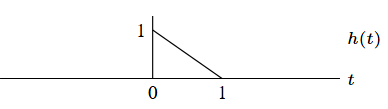

And the input to the system be x(t) = u(t). Find the step response to the system, in other words find y(t) = x(t)*h(t) = u(t)*h(t).

For this example, let's use $-10 \leq t\leq 10$. This range of t values allows us to properly capture all the relevant behaviour of the system. For density, let's use a step size of 0.01.

Firstly let's create both vectors x and h and plot them:

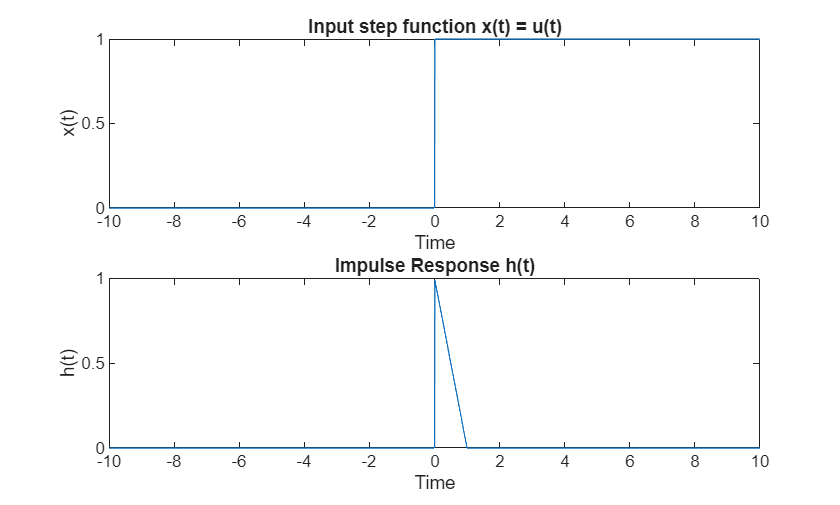

%Define time vector:
dt = 0.01;           
t = -10:dt:10;

%Define input:
x = double(t>0); %Note, if you omit the double() x will be a logical array
%Or if you like symbols you can use:
%x = double(heaviside(t))

%Now define h (the method below is just one I find easiest)
a = double(t>0);
b = double(t-1>0);
h = (1-t).*(a-b);
figure;
subplot(2,1,1);
plot(t,x);
xlabel('Time');
ylabel('x(t)');
title('Input step function x(t) = u(t)');
subplot(2,1,2);
plot(t,h);
xlabel('Time');
ylabel('h(t)');
title('Impulse Response h(t)');

Recall that the convolution operator doesn't care which vector is flipped 180 degrees, so long as one and only one of them is flipped due to the commutivity of the convolution operator. There are two main methods or performing convolution in MATLAB, the first is a manual convolution and the second is a built in convolution function. 

#### Method 1: Manual Convolution

NOTE: There are some sections of code omitted here, as this will form a skeleton for some of the lab questions. You need to figure them out! You can always test your answers by doing the convolution by hand, and comparing to your plot outputs.

I will choose to flip the step function:

x_flipped = fliplr(x);

Now that one of the vectors has been flipped, all we need to do is iteratively evaluate the pointwise summed product of their elements as we slide x_flipped over the elements of h. Note that the two vectors were constructed from the same domain, and hence have the same size m = n. As x_flipped needs to slide COMPLETELY over h, with the first instance being an overlap of the first elements, and the last being the overlap of the ends. This means that we need to pad h with the length of (x - 1) on each side.

%Pad the h vector:
L_x = length(x_flipped);
L_h = length(h);
h_pad = %How to pad vectors? [padvector1, h, padvector2]. Consider using the zeros function     

Now to fill y:

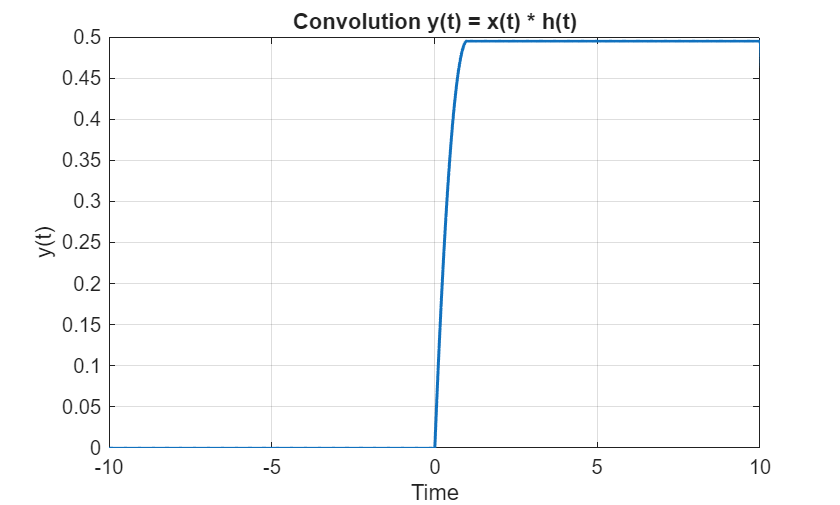

%Initialize y_manual
L_y = %How long must y be with respect to the lengths of x and h?
y_manual = %Initialize with zeros

% Slide x_flipped across h_pad
for i = 1:L_y
    y_manual(i) = %summed product of x_flipped and h_pad... remember it is element wise
    % And you need to multiply by dt as it is an integral
end

%Define time vector corresponding to y
t_y = linspace(t(1)+t(1), t(end)+t(end), L_y); %Think about why it is more dense than 't'

% Plot the trimmed convolution
figure;
plot(t_y, y_manual, 'LineWidth',1.5);
xlabel('Time'); ylabel('y(t)');
title('Convolution y(t) = x(t) * h(t)');
grid on;
%Please note that because we are using finite length vectors for x and h,
%we need to trim the output t-axis to only include values where we have
%defined them. Any values further will exhibit behaviour not in keeping
%with the theory. Try increasing xlim and you will notice that y(t) goes
%down to zero as t increases past 10, as there are no more non-zero points
%of overlay. This is overcome by increasing the time vectors size.
xlim([-10, 10])

#### Method 2: Built in convolution

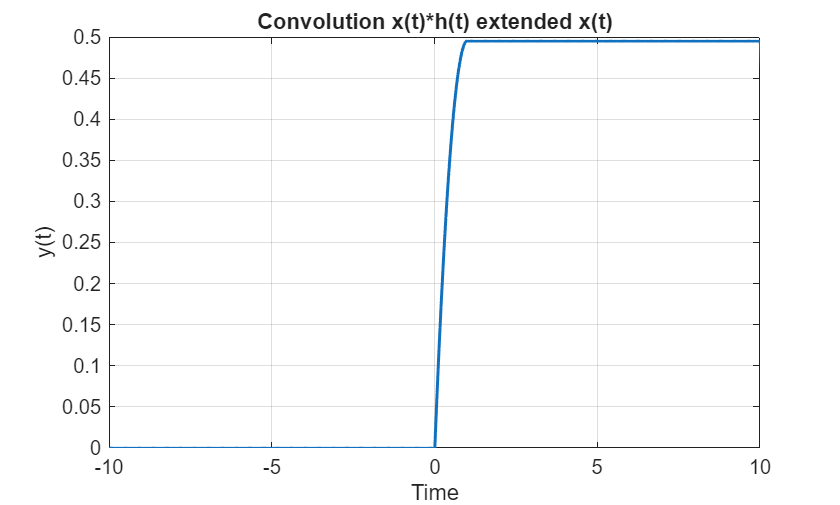

%Define time vector:
dt = 0.01;           
t = -10:dt:10; 

x = double(t>0); 
a = double(t>0);
b = double(t-1>0);
h = (1-t).*(a-b);

%Convolution
y = conv(x,h)*dt;
t_y = t(1) + t(1):dt:t(end) + t(end); 

figure;
plot(t_y, y,'LineWidth',1.5)
xlabel('Time'); ylabel('y(t)')
title('Convolution x(t)*h(t) extended x(t)')
grid on
%Please note, you need to set t-axis limits as below because even though we
%know the output remains at y = 1/2 for all t>=1, we have finite vectors so
%it will taper off after x has reached its end.
xlim([-10, 10]);

## Section 4: Solving convolution questions with differential equations

Recall from class that when you take the derivative of two convolved functions, the derivative operator acts on only one of them, and it doesn't matter which one. In other words for y(t) = x(t)*h(t):


$$
\dot{y}(t) = \dot{x}(t)*h(t) = x*\dot{h}(t)


$$


This means that if you can easily evaluate the RHS all you need to do is integrate both sides to find y(t). Note that this is also a first order ordinary differential equation, which can be solved with built in differential equation solvers, such as ode45 or direct integration through symbolic maths

Take the example:

Taking the derivative of both sides:


$$\dot{y}(t) = \dot{x}(t)*h(t) = (\frac{d}{dt}u(t-1))*e^{-t}u(t) = \delta(t-1)*e^{-t}u(t) = e^{-(t-1)}u(t-1)$$


Now to define the RHS of the equation:

syms t tau

%Define RHS of the equation
f = exp(-(tau-1)) * heaviside(tau-1);
%Note if the RHS is hard to evalutate by hand, use the built in diff
%function but beware of deltas that may pop up, handle them properly.

%Integrate both sides from -infinity to t
y = int(f, tau, -inf, t);

%simplify/piecewise form
y = simplify(y)

$$y = \frac{{\mathrm{e}}^{1-t}\,\left({\mathrm{e}}^{t-1}-1\right)\,\left(\mathrm{sign}\left(t-1\right)+1\right)}{2}$$

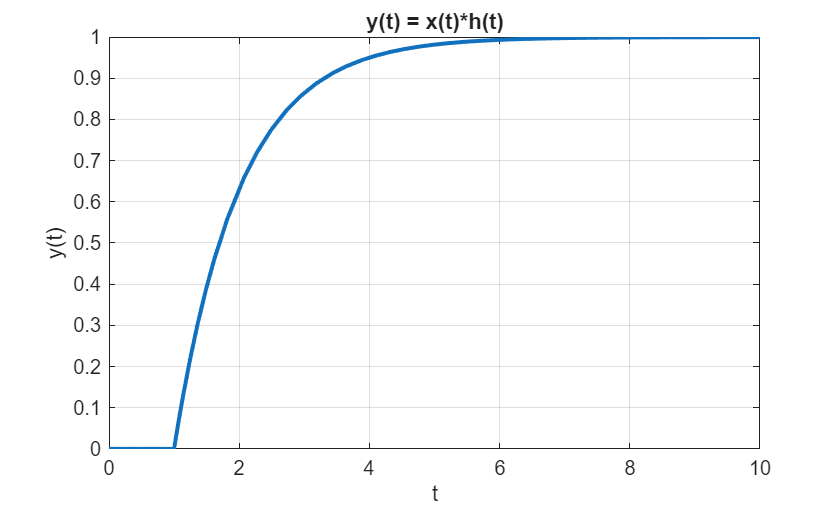

fplot(y, [0 10], 'LineWidth', 2)
grid on
xlabel('t')
ylabel('y(t)')
title('y(t) = x(t)*h(t)')

Another method to solve these types of ordinary differential equations is to use ode45. This built in MATLAB ODE solver can be used to find solutions to systems of ODEs, and has the following syntax:

%[t,y] = ode45(odefun,tspan,y0)

Where t is the output domain, y is a MATRIX with each column being a solution to a specific ODE present in the system y = [y1|y2|...|yn]. odefun is a function that describes the RHS of an ODE, tspan is a 1x2 row vector containing [t_min, t_max] and y0 is a row vector of initial conditions. Consider the following example:


$$y'  = 2t
$$


Subject to the initial condition y(0) = 0, existing for the range of time: $0\le t \le5
$.

The solution to this ODE is hence:

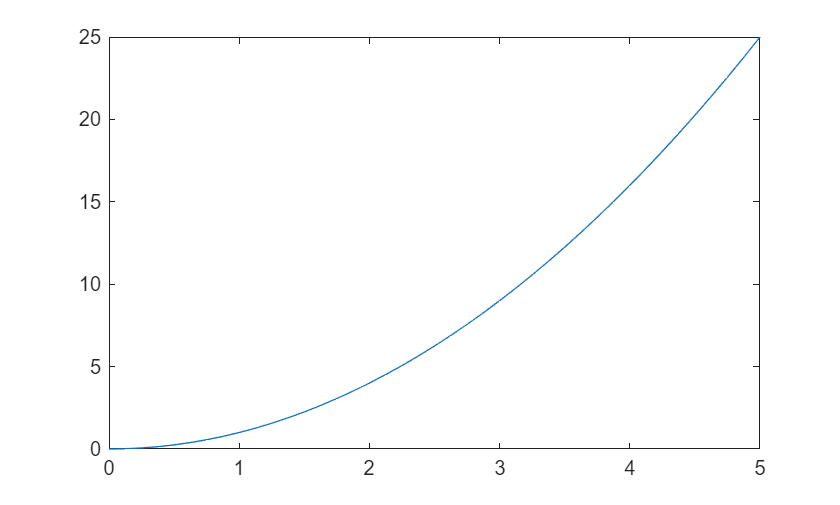

tspan = [0, 5];
y0 = 0; 
[t,y] = ode45(@(t,y) 2*t, tspan, y0);
plot(t,y)

## Section 5: Questions

#### Question 1:

Modify the above code for the **MANUAL** convolution to create a MATLAB function that computes the convolution of two vectors. The function needs to take in the three vectors as inputs *t*, *x* and *h*, and output a single vector *y_manual* being the convolution of the two. It also needs to output 4 subplots, the first one being a plot of x, the second being h, the third being a flipped version of x, and the final being a plot of y_manual. A template will be provided in the code block pre-labelled. Use t between -10 and 10 with step size 0.01. Remember to limit xlims on the y_manual plot to be between -10 and 10!

Use the following functions as inputs:

- 
$$h(t) = e^{-t}u(t)$$


- 
$$x(t) = u(t)
$$


Call the function *computeConv*.  

#### Question 2:

Given a general RC circuit, with input voltage:


$$V(t) = sin(t)u(t)$$


Derive an expression and plot the voltage across the capacitor (Vc(t)). The ODE is subject to Vc(0) = 0, and R = $100
\Omega
$ and C = $1
 F
$. Assume t ranges from 0 to 20 seconds.

Firstly, solve this expression using ode45. Secondly, compute the result using symbolic processing via the convolution integral. Recall for an RC circuit:


$$h(t) = \frac{1}{RC} e^\frac{-t}{RC}u(t)$$


Compute the convolution integral namely with integrand Vc(t) = h(t) * V(tau). Remember to use SYMBOLIC processing. You can evaluate your answer by via the simplify, double and subs functions.

Finally, calculate the difference between the ode45 solution and the symbolic convolution. Store their difference in a vector called *difference.*

*Hint: Shift h in the convolution integral, and integrate from 0 to t. Remember the integrand is a function of tau besides the shifted h(t-tau).*

#### Question 3:

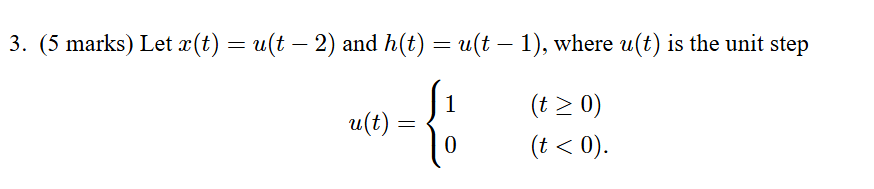

Find y _sym= x*h using symbolic processing for t = -10 to 10 and plot it. Define the RHS of y' = f and store in a variable named 'f'. Define x and h numerically.